clear all;

% wind_speeds = linspace(0,4,100);
% angles_of_attack = zeros(1,length(wind_speeds));
% 
% for i=1:length(wind_speeds)
%     angles_of_attack(i) = rad2deg(wrapTo2Pi(alpha_from_wind_speed(wind_speeds(i))));
% end

% angle_difference = angles_of_attack-10;
% for i=1:length(wind_speeds)
%     if angle_difference(i) <= 3
%         if angle_difference(i) >= 0.5
%             min_stable = wind_speeds(i);
%             break
%         end
%     end
% end


wind_speeds = linspace(0.9,3,50);
angles_of_attack = zeros(1,length(wind_speeds));

x_bridle_sweep = linspace(0.05,0.4,30);
y_bridle = -0.23;                                                                          
min_stable = zeros(length(x_bridle_sweep), 1)+10;

for i=1:length(x_bridle_sweep)
    %calculate the angles of attack at each wind speed for the bridle point
    for I = 1:length(wind_speeds)
        angles_of_attack(I) = rad2deg(wrapTo2Pi(alpha_from_wind_speed_bridle_variable(wind_speeds(I), x_bridle_sweep(i), y_bridle)));
    end
    angle_difference = angles_of_attack-10;
    for index = 1:length(angle_difference)
        if angle_difference(index) <= 3
            if angle_difference(index) >= 0.5          
                min_stable(i) = wind_speeds(index);
                break
            end
        else
            min_stable(i) = 10;
        end
    end
end
[m, x_min_index] = min(min_stable)

m = 0.9429

x_min_index = 14

initial_x_bridle = x_bridle_sweep(x_min_index)

initial_x_bridle = 0.2069


wind_speeds = linspace(0.9,3,50);
angles_of_attack = zeros(1,length(wind_speeds));

y_bridle_sweep = linspace(-0.05,-0.4,30);                                                                         
min_stable_y = zeros(length(y_bridle_sweep), 1)+10;

for i=1:length(y_bridle_sweep)
    for I = 1:length(wind_speeds)
        angles_of_attack(I) = rad2deg(wrapTo2Pi(alpha_from_wind_speed_bridle_variable(wind_speeds(I), initial_x_bridle, y_bridle_sweep(i))));
    end
    angle_difference = angles_of_attack-10;
    for index = 1:length(angle_difference)
        if angle_difference(index) <= 3
            if angle_difference(index) >= 0.5  
                min_stable_y(i) = wind_speeds(index);
                break
            end
        else
            min_stable_y(i) = 10;
        end
    end
end

[m, y_min_index] = min(min_stable_y)

m = 0.9429

y_min_index = 14

initial_y_bridle = y_bridle_sweep(y_min_index)

initial_y_bridle = -0.2069

wind_speeds = linspace(0.9,3,50);
angles_of_attack = zeros(1,length(wind_speeds));

x_bridle_sweep = linspace(initial_x_bridle - 0.1,initial_x_bridle + 0.1,30);
y_bridle = initial_y_bridle;                                                                          
min_stable = zeros(length(x_bridle_sweep), 1)+10;

for i=1:length(x_bridle_sweep)
    %calculate the angles of attack at each wind speed for the bridle point
    for I = 1:length(wind_speeds)
        angles_of_attack(I) = rad2deg(wrapTo2Pi(alpha_from_wind_speed_bridle_variable(wind_speeds(I), x_bridle_sweep(i), y_bridle)));
    end
    angle_difference = angles_of_attack-10;
    for index = 1:length(angle_difference)
        if angle_difference(index) <= 3
            if angle_difference(index) >= 0.5          
                min_stable(i) = wind_speeds(index);
                break
            end
        else
            min_stable(i) = 10;
        end
    end
end
[m, x_min_index] = min(min_stable)

m = 0.9429

x_min_index = 15

final_x_bridle = x_bridle_sweep(x_min_index)

final_x_bridle = 0.2034

wind_speeds = linspace(0.9,3,50);
angles_of_attack = zeros(1,length(wind_speeds));

y_bridle_sweep = linspace(initial_y_bridle+0.1,initial_y_bridle-0.1,30);                                                                         
min_stable_y = zeros(length(y_bridle_sweep), 1)+10;

for i=1:length(y_bridle_sweep)
    for I = 1:length(wind_speeds)
        angles_of_attack(I) = rad2deg(wrapTo2Pi(alpha_from_wind_speed_bridle_variable(wind_speeds(I), final_x_bridle, y_bridle_sweep(i))));
    end
    angle_difference = angles_of_attack-10;
    for index = 1:length(angle_difference)
        if angle_difference(index) <= 3
            if angle_difference(index) >= 0.5  
                min_stable_y(i) = wind_speeds(index);
                break
            end
        else
            min_stable_y(i) = 10;
        end
    end
end

[m, y_min_index] = min(min_stable_y)

m = 0.9000

y_min_index = 19

final_y_bridle = y_bridle_sweep(y_min_index)

final_y_bridle = -0.2310

wind_speeds = linspace(0.9,4,51);
angles_of_attack = zeros(1,length(wind_speeds));
F_tension = zeros(length(wind_speeds), 3);
omega = zeros(1,length(wind_speeds));
wrapped_alpha = zeros(1,length(wind_speeds));

for i=1:length(wind_speeds)
    [angles_of_attack(i), F_tension(i,:), omega(i), wrapped_alpha(i)] = alpha_from_wind_speed_bridle_variable(wind_speeds(i), final_x_bridle, initial_y_bridle);
end


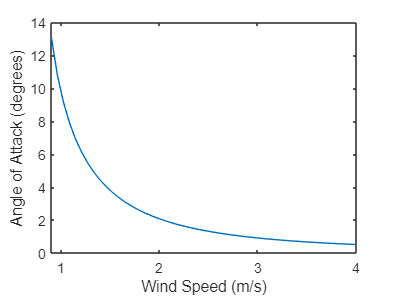



hold off
plot(wind_speeds,wrapped_alpha); 
xlabel("Wind Speed (m/s)")
ylabel("Angle of Attack (degrees)")

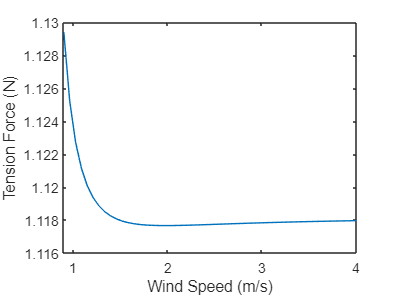

tension_magnitude = zeros(1,length(F_tension));
for i = 1:length(F_tension)
    tension_magnitude(i) = norm(F_tension(i,:));
end
plot(wind_speeds,tension_magnitude); 
xlabel("Wind Speed (m/s)")
ylabel("Tension Force (N)")

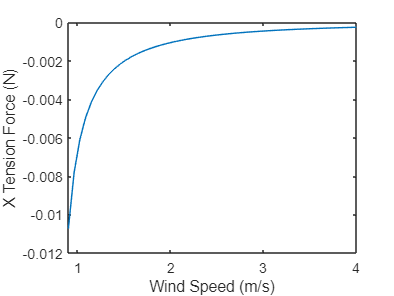


plot(wind_speeds, F_tension(:,1))
xlabel("Wind Speed (m/s)")
ylabel("X Tension Force (N)")

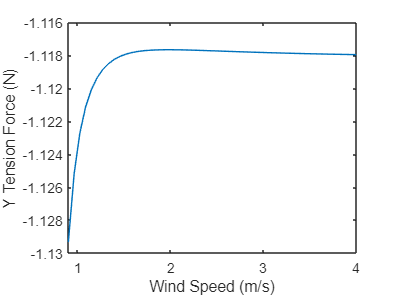


plot(wind_speeds, F_tension(:,2))
xlabel("Wind Speed (m/s)")
ylabel("Y Tension Force (N)")

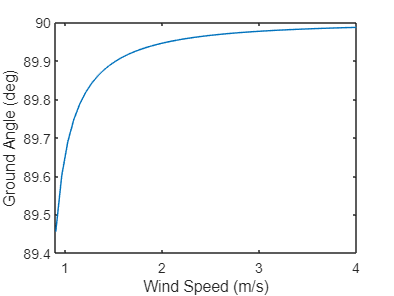

plot(wind_speeds,omega); 
xlabel("Wind Speed (m/s)")
ylabel("Ground Angle (deg)")

function [angle_of_attack, F_tension, omega]=alpha_from_wind_speed(velo)
syms alpha_
% Kite dimensions and properties
major_axis_length = 0.7; % kite vertical axis length in meters
minor_axis_length = 0.7; % kite horizontal axis length in meters
A_s = 0.5*major_axis_length*minor_axis_length; % surface area of kite in square meters
A_f = A_s*sin(alpha_); % frontal area of kite in square meters
mass = 0.1; % mass of kite in kilograms
gravity = 9.81; % acceleration due to gravity
% Air properties
rho = 1.2754; % density of air in kg/m^3
velocity = velo; % air speed in m/s
% coordinate origin is tip of leading edge
center_of_mass = [major_axis_length*0.5*cos(alpha_) -major_axis_length*0.5*sin(alpha_) 0];
center_of_pressure = [major_axis_length*0.25*cos(alpha_) -major_axis_length*0.25*sin(alpha_) 0];
bridle_point=center_of_pressure+[-0.175,-0.2,0];
% radii for moments
r_p = center_of_pressure-bridle_point;
r_g = center_of_mass-bridle_point;
% forces
lift_coefficient = 2*pi*alpha_/(1+2*A_s*alpha_/minor_axis_length);
F_lift = [0, (pi*alpha_*rho*velocity^2*A_s)/(1 + (2*A_s*alpha_/(minor_axis_length^2))), 0];
F_drag = [((rho*velocity^2*A_f)/2)*(1.28*alpha_ + (A_f*lift_coefficient^2)/(0.7*pi*minor_axis_length^2)), 0, 0];
F_gravity = [0,  -mass*gravity, 0];
% moments
lift_moment = cross(r_p, F_lift);
drag_moment = cross(r_p, F_drag);
gravity_moment = cross(r_g, F_gravity);
eqn = lift_moment(3)+drag_moment(3)+gravity_moment(3) == 0;
angle_of_attack = double(vpasolve(eqn, alpha_)); % angle of attack in radians
F_tension = [-F_drag(1) F_gravity(2)-F_lift(2) 0]; %Tension Force in Newtons
omega = atand(F_tension(2)/F_tension(1)); % angle from ground in deg
end

function [angle_of_attack, F_tension, omega, wraped_alpha]=alpha_from_wind_speed_bridle_variable(velo, x_bridle, y_bridle)
syms alpha_
% Kite dimensions and properties
major_axis_length = 0.7; % kite vertical axis length in meters
minor_axis_length = 0.7; % kite horizontal axis length in meters
A_s = 0.5*major_axis_length*minor_axis_length; % surface area of kite in square meters
A_f = A_s*sin(alpha_); % frontal area of kite in square meters
mass = 0.1; % mass of kite in kilograms
gravity = 9.81; % acceleration due to gravity
% Air properties
rho = 1.2754; % density of air in kg/m^3
velocity = velo; % air speed in m/s
% coordinate origin is tip of leading edge
center_of_mass = [major_axis_length*0.5*cos(alpha_) -major_axis_length*0.5*sin(alpha_) 0];
center_of_pressure = [major_axis_length*0.25*cos(alpha_) -major_axis_length*0.25*sin(alpha_) 0];
bridle_point=center_of_pressure+[x_bridle, y_bridle, 0];
% radii for moments
r_p = center_of_pressure-bridle_point;
r_g = center_of_mass-bridle_point;
% forces
lift_coefficient = 2*pi*alpha_/(1+2*A_s*alpha_/minor_axis_length);
F_lift = [0, (pi*alpha_*rho*velocity^2*A_s)/(1 + (2*A_s*alpha_/(minor_axis_length^2))), 0];
F_drag = [((rho*velocity^2*A_f)/2)*(1.28*alpha_ + (A_f*lift_coefficient^2)/(0.7*pi*minor_axis_length^2)), 0, 0];
F_gravity = [0,  -mass*gravity, 0];
% moments
lift_moment = cross(r_p, F_lift);
drag_moment = cross(r_p, F_drag);
gravity_moment = cross(r_g, F_gravity);
eqn = lift_moment(3)+drag_moment(3)+gravity_moment(3) == 0;
% Solved Values
angle_of_attack = double(vpasolve(eqn, alpha_)); % angle of attack in radians
wraped_alpha = rad2deg(wrapTo2Pi(angle_of_attack));
F_lift = subs(F_lift, alpha_, angle_of_attack);
F_drag = subs(F_drag, alpha_, angle_of_attack);
F_tension = double([-F_drag(1) F_gravity(2)-F_lift(2) 0]); %Tension Force in Newtons
omega = double(atand(F_tension(2)/F_tension(1))); % angle from ground in deg
end